# Interface para o método de RK2 e RK4

CHAMADA DE FUNÇÕES:

    RK2

    RK4

    dsolve

26/03/2021  Arménio Correia  armenioc@isec.pt

Trabalho realizado por:(23/04/2021)

        Diogo Silva - 2020138438 - a2020138438@isec.pt

        Hugo Ferreira - 2020128305 - 2020128305@isec.pt

        Rúben Mendes  - 2020138473 - a2020138473@isec.pt

clc
clear

syms y(t)

strF = input('f(t,y) = ','s');
f = @(t,y)eval(vectorize(strF));
disp('----- Método RK2 e RK4 ------ ');

----- Método RK2 e RK4 ------ 


a  = str2num(input('a = ','s'));
b  = str2num(input('b = ','s'));
n  = str2num(input('n = ','s'));
y0 = str2num(input('y0 = ','s'));

tic
yRK2 = NRK2(f,a,b,n,y0)

yRK2 = 	1.0e+03 *

    0.0060    0.0144    0.0446    0.1724    0.8192    4.6989


toc

Elapsed time is 0.020527 seconds.


tic
yRK4 = NRK4(f,a,b,n,y0)

yRK4 = 	1.0e+04 *

    0.0006    0.0016    0.0056    0.0269    0.1747    1.5141


toc

Elapsed time is 0.019067 seconds.



sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = 6\,{\mathrm{e}}^{t^{2}}\,{\mathrm{e}}^{-1}$$

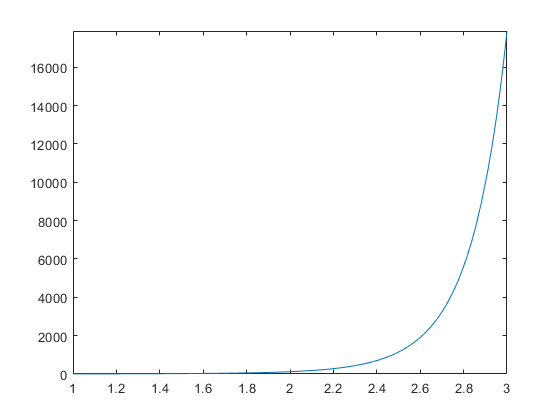

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroRK2 = abs(yExata-yRK2);
erroRK4 = abs(yExata-yRK4);
disp('----- Tabela de Valores ------ ');

----- Tabela de Valores ------ 


tabela = [t.',yExata.',yRK2.',yRK4.',erroRK2.',erroRK4.'];
array2table(tabela,"VariableNames",{'t','Exata','RK2','RK4','Erro RK2','Erro RK4'})

ans = 6×6 table
     t     Exata      RK2       RK4       Erro RK2      Erro RK4 
    ___    ______    ______    ______    __________    __________

      1         6         6         6    1.7764e-15    1.7764e-15
    1.4     15.67    14.448    15.616        1.2222      0.054204
    1.8     56.36    44.592    55.575        11.768       0.78545
    2.2    279.15    172.45    268.59        106.71        10.561
    2.6    1904.1    819.19    1747.2        1084.9        156.86
      3     17886    4698.9     15141         13187        2744.8



disp('----- Gráfico de Soluções ------ ');

----- Gráfico de Soluções ------ 


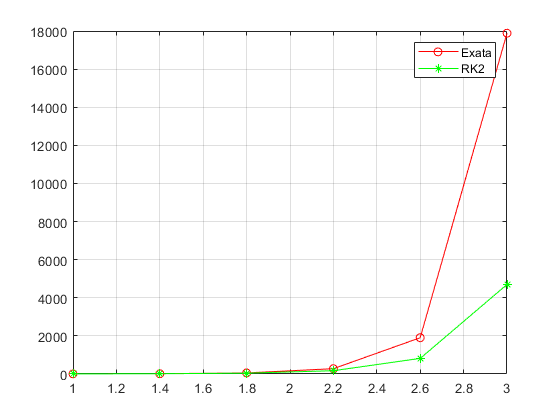

plot(t,yExata,"-ro")
hold on
plot(t,yRK2,"-g*")
hold off
grid on
legend('Exata','RK2')

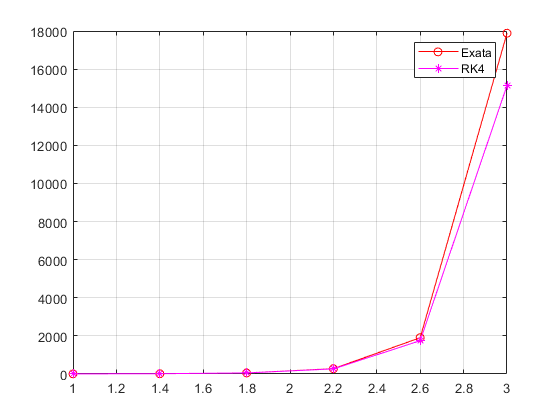



plot(t,yExata,"-ro")
hold on
plot(t,yRK4,"-m*")
hold off
grid on
legend('Exata','RK4')